% This script was used to produce both three-dimensional (3D) and 
% two-dimensional (2D) distributions. Both for instructional and demonstration purposes. 

% MPhys Research Project 2022/23
% Ross Anderson (H00295702)



%clear commands
clc
clear

%3D coordinate system

res = 256;  %image resolution
x = linspace(-1,1,res); %in terms of -1 and 1

[X,Y,Z] = meshgrid(x);  %meshgrid to create coord system

R = sqrt(X.^2+Y.^2+Z.^2);   %radius, defined in polar coords

cos_theta = Z./R;

P = atan2(X,Y);

P2 = 0.5*(3*cos_theta.^2 - 1);   %Y20 spherical harmonic

Y22 = (1-cos_theta.^2).*cos(2*P);

%spherical 3D distribution
I=exp(-((R-0.7)/0.05).^2);

figure()
% VMIisosurf(I,1,'full');

%second Legendre polynomial 3D distribution (cylindrical)
I = exp(-((R-0.7)/0.05).^2).*P2;

figure()
% VMIisosurf(I,1,'full')

%Y22 spherical harmonic 3D distribution
I = exp(-((R-0.7)/0.05).^2).*Y22;

figure()
% VMIisosurf(I,1,'full')

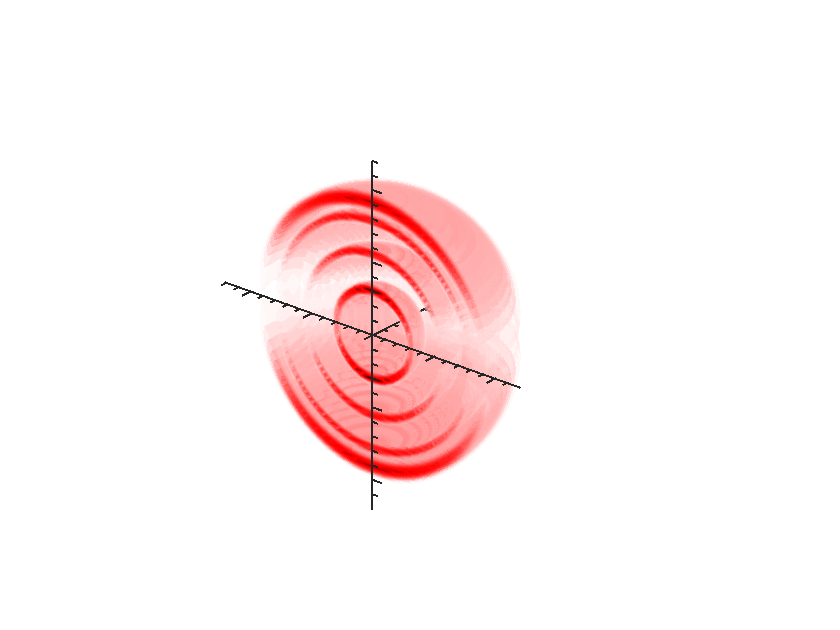

%abel transform
I1 = exp(-((R-0.9)/0.04).^2).*(1 + 1.75*P2);
I2 = exp(-((R-0.775)/0.02).^2).*(1 + 1.625*P2);    %p-orbital
I3 = exp(-((R-0.55)/0.02).^2).*(1 + 1.75*P2);
I4 = 2*exp(-((R-0.3)/0.02).^2).*(1 + 1*P2);

I = I1 + I2 + I3 + I4;

figure()
VMIisosurf(I,1,'half')

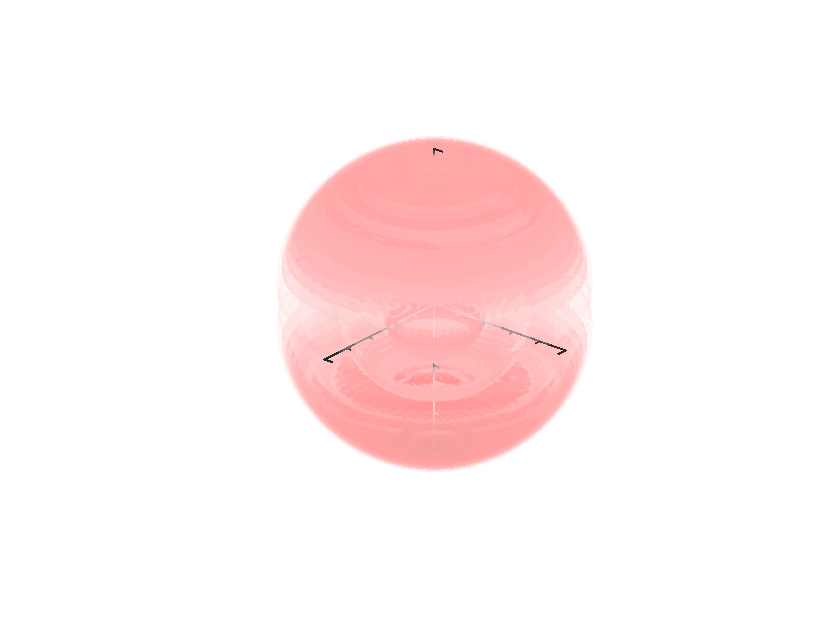


figure()
VMIisosurf(I,1,'full')

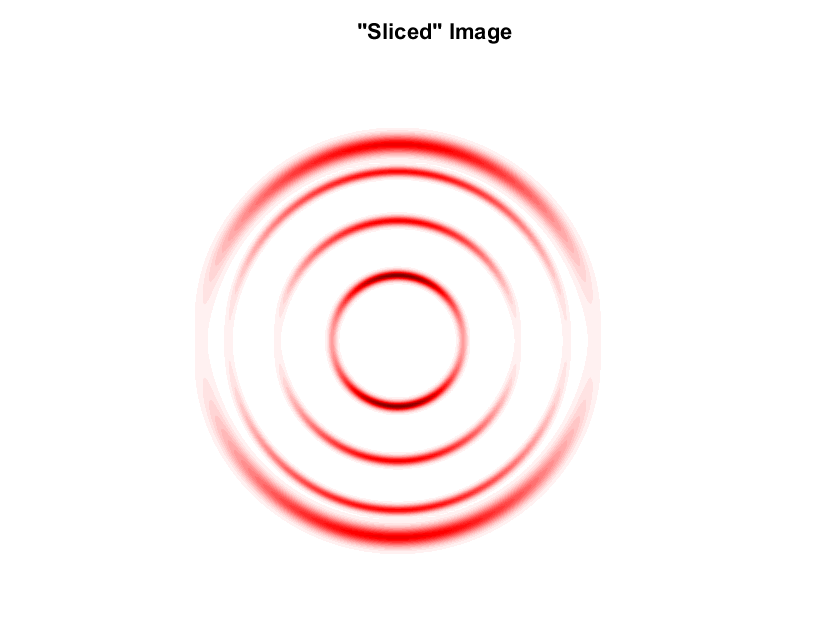


I_2D_slice = squeeze(I(:,res/2,:))';

figure
showim(I_2D_slice,1)
title('"Sliced" Image')

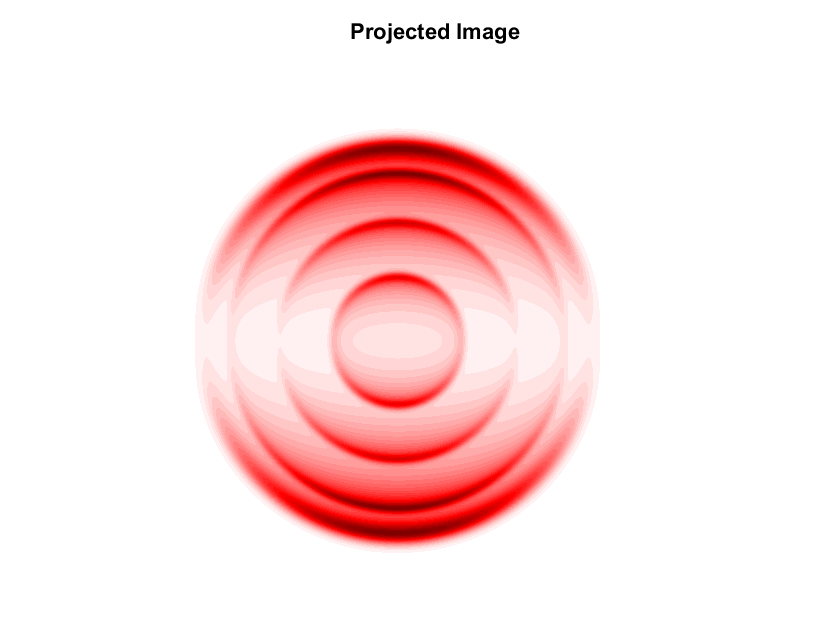


I_2D_projection = squeeze(sum(I,2))';

figure
showim(I_2D_projection,1)
title('Projected Image')

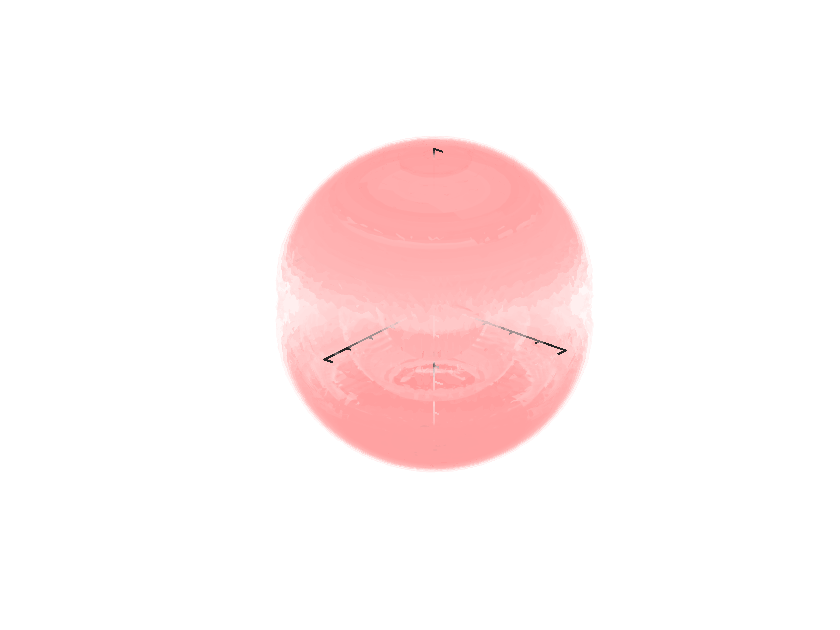




I = I/sum(I, 'all');

counts = I*10^7;
I_sampled = poissrnd(counts, size(I, 1), size(I, 2), size(I, 3));

figure()
VMIisosurf(I_sampled, 1, 'full')

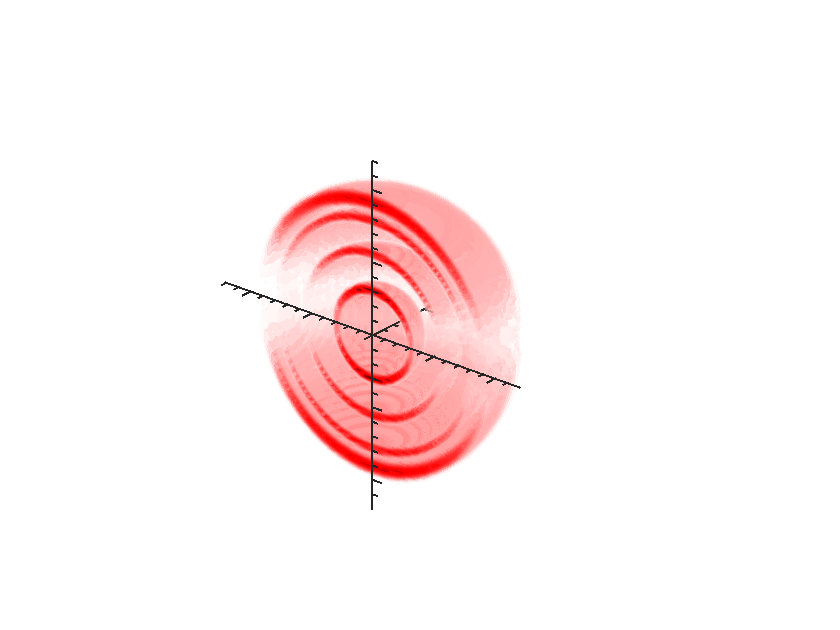


figure()
VMIisosurf(I_sampled, 1, 'half')

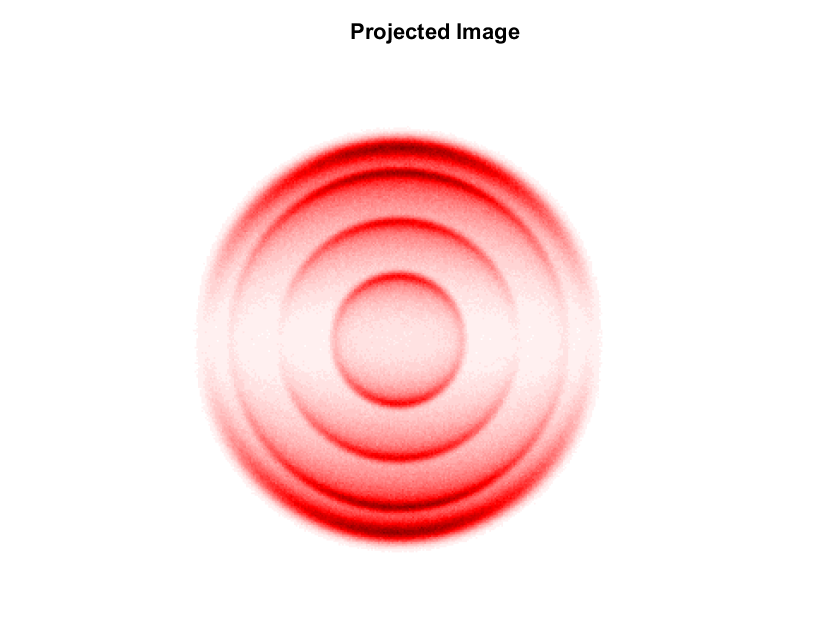


I_2D_projection = squeeze(sum(I_sampled,2))';

figure
I_2D_projection = rescale(I_2D_projection);

showim(I_2D_projection,1)
title('Projected Image')
shading flat

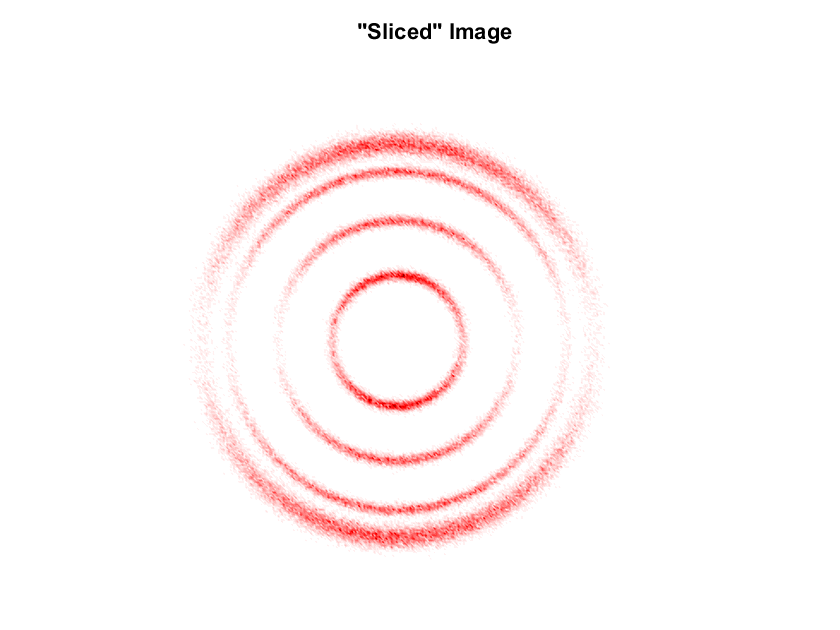


I_2D_slice = squeeze(I_sampled(:,res/2,:))';

figure()
showim(I_2D_slice,1)
title('"Sliced" Image')

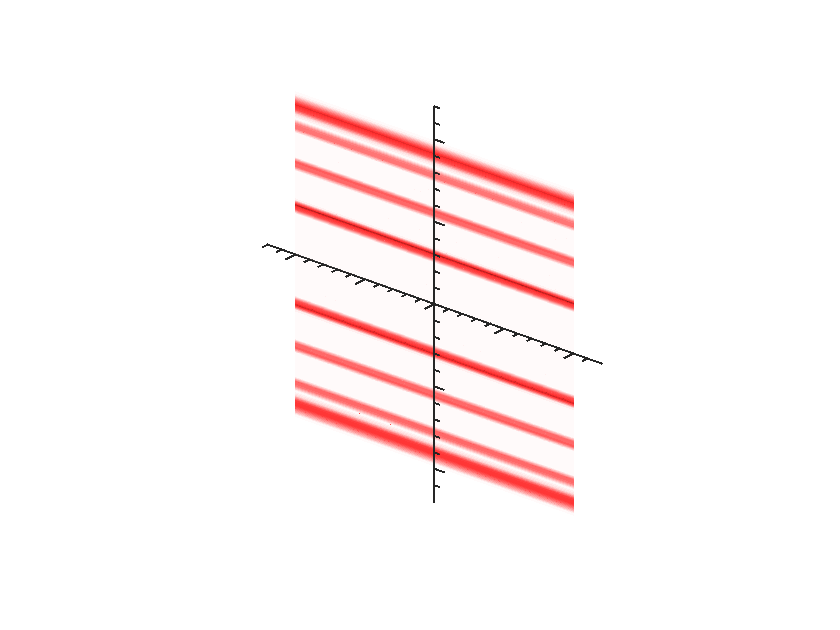


figure()
VMIisosurf(I_sampled(end/2, :, :), 1, 'slice')

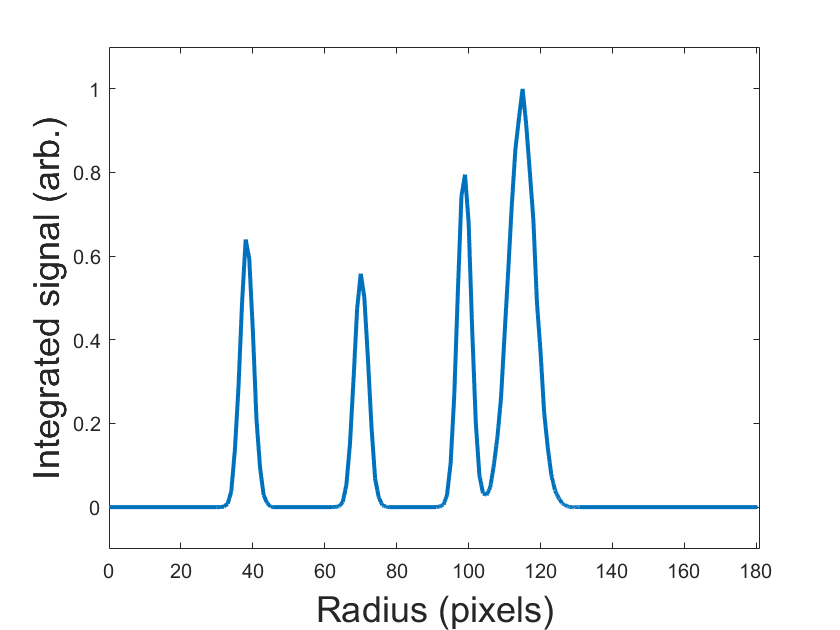






[integrated, interp_integrated, radii, theta_whole] = integrateim2(I_2D_slice, 256);

% network input
figure()
interp_integrated = interp_integrated/max(interp_integrated);
plot(radii, interp_integrated, "LineWidth", 2)
% title("Velocity distribution - Network input")
xlim([0, max(radii)])
% xlim([0, 40])
ylim([-0.1, 1.1])
xlabel("Radius (pixels)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)

% %2D coordinate system - much easier!
%
% res = 256;
% x = linspace(-1,1,res);
%
% [X,Y] = meshgrid(x);
%
% R = sqrt(X.^2 + Y.^2);
%
% cos_theta = Y./R;
%
% P2 = 0.5*(3*cos_theta.^2 - 1);
%
% P4 = (1/8)*(35*cos_theta.^4 - 30*cos_theta.^2 + 3);

% %randomly set amplitude
% A0 = 0.2 + (1-0.2)*rand;
%
% %randomly set radius
% R0 = 0.1 + (0.7-0.1)*rand;
%
% %randomly set width
% W0 = 0.05 + (0.2-0.05)*rand;
%
% %? beta2?
% B2 = 1.3;
%
% I = A0*exp(-((R-R0)/W0).^2).*(1 + B2*P2);
%
% showim(I,1)
% title('Simulated')
%
% I_Abel = Abel(I);
%
% showim(I_Abel,1);
% title('Simulated Abel')